Load the data and find the SVD.

Faces = load("yalefaces.mat");
Faces = Faces.X;
[U,D,V]=svd(Faces);

View a few faces in the database.

face = 1

face = 1

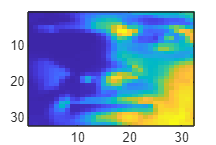

imagesc(flip(rot90(reshape(Faces(:,face),32,32))))

Next we view the first few (up to 10) left singular vectors as images, these are the eigenfaces. Perhaps you can see some aspects of faces represented by each.

n =1

n = 1

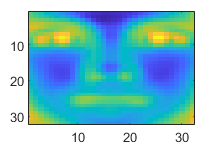

imagesc(flip(rot90(reshape(U(:,n),32,32))))

DD = diag(D).^8;
p = sum(DD(1:n))/sum(DD);
text = sprintf('%.2f%% of the information in the faces \n is in the first %i eigenvextors.', [p*100, n]);
display(text);

text =     '99.81% of the information in the faces 
      is in the first 1 eigenvextors.'


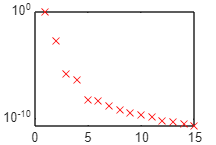

semilogy(DD(1:15)./sum(DD),'xr')